% Comandos para la PowerShell:
  % cd C:\Users\usuario\Desktop\Renate-files\files
  % Dir|%{Rename-Item $_ -NewName ("Renate_{0}.txt" -f $nr++)}

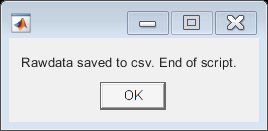

clear 
clc

% Obtener el número de archivos de datos en la carpeta  
listFiles = dir('C:\Users\usuario\Desktop\Renate-files\files\*.txt');
numFiles = numel(listFiles);

% Extraer la información de cada archivo y ponerla toda junta

rawdata = [];

for i=0:(numFiles-1)
    
    myfilename=['C:\Users\usuario\Desktop\Renate-files\files\Renate_',num2str(i),'.txt'];
    rawdata = [rawdata; importfile(myfilename)];
    
end

% Eliminar el sufijo -DRAIN de los nombres que lo tienen
rawdata.Type = erase(rawdata.Type,'-DRAIN');

% Eliminar las filas que corresponden a encabezado de tabla y órdenes d Go to sleep y
% Wake up
rawdata(rawdata.Type == 'Type', :) = [];
rawdata(rawdata.Type == 'GO TO SLEEP', :) = []; 
rawdata(rawdata.Type == 'WAKE UP', :) = [];
rawdata(rawdata.Type == 'SHUT DOWN', :) = [];

% Guardar los datos en un csv
ask1 = "Rawdata table created. Generate csv file? y/n ";
answer1 = input(ask1, "s");

if answer1 == "y"
    ask2 = "Name of file? (date): ";
    csvName = "C:\Users\usuario\Desktop\Renate-files\" + input(ask2, "s") + ".csv";
    writetable(rawdata, csvName, "Delimiter", "\t");
    msgbox("Rawdata saved to csv. End of script.");
else
    msgbox("Rawdata not saved to csv. End of script.");
end